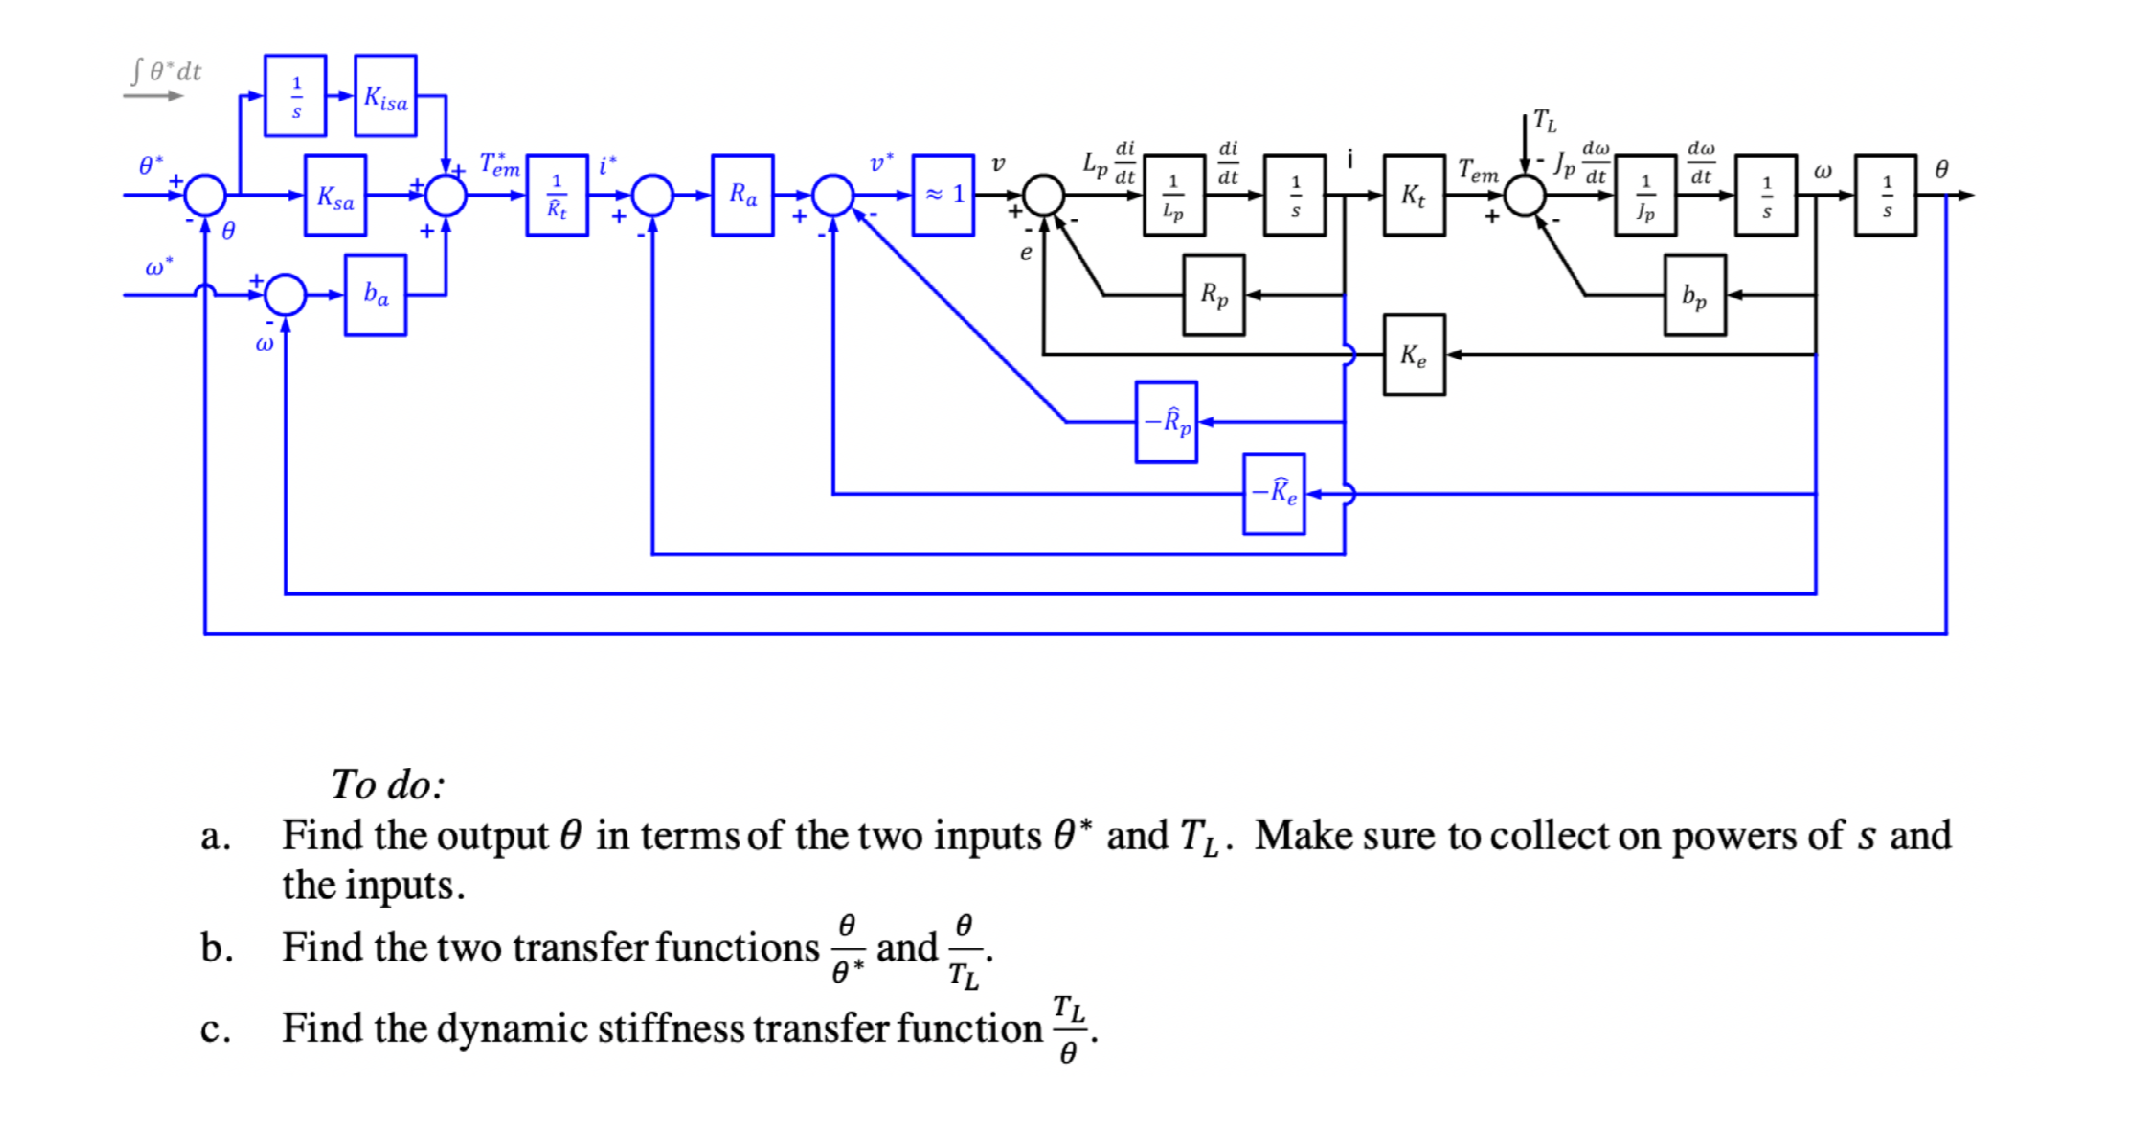

% EEP 557 HW1
% Qingchuan Hou

imshow(imread("HW1/HW1.png"))


syms theta omega J_p s T_em T_L b_p i K_t L_p K_e R_p v v_ast R_a i_ast R_hat_p K_hat_e T_ast_em K_hat_t theta_ast K_isa K_sa omega_ast b_a


## basic equations

% Black Block
eq1 = theta == omega * 1/s

$$eq1 = \theta =\frac{\omega }{s}$$

eq2 = J_p * (s * omega) == T_em - T_L - b_p*omega           % J_p

$$eq2 = J_{p}\,\omega \,s=T_{\mathrm{em}}-T_{L}-b_{p}\,\omega$$

eq3 = T_em == i * K_t                                       % T_em

$$eq3 = T_{\mathrm{em}}=K_{t}\,i$$

eq4 = L_p * (s * i) == v - omega*K_e - i*R_p                % L_p

$$eq4 = L_{p}\,i\,s=v-K_{e}\,\omega -R_{p}\,i$$


% Blue Block
eq5 = v == 1 * v_ast

$$eq5 = v=v^{*}$$

eq6 = v_ast == R_a * (i_ast - i) + i*R_hat_p + omega*K_hat_e     % v_ast   

$$eq6 = v^{*}={\hat{K}}_{e}\,\omega +{\hat{R}}_{p}\,i-R_{a}\,\left(i-i^{*}\right)$$

eq7 = i_ast == T_ast_em * 1/K_hat_t                             % i_ast

$$eq7 = i^{*}=\frac{{T^{*}}_{\mathrm{em}}}{{\hat{K}}_{t}}$$

eq8 = T_ast_em == (theta_ast-theta) * (1/s * K_isa + K_sa) + (theta_ast*s - omega) * b_a    % T_ast_em    

$$eq8 = {T^{*}}_{\mathrm{em}}=-\left(K_{\mathrm{sa}}+\frac{K_{\mathrm{isa}}}{s}\right)\,\left(\theta -\theta^{*}\right)-b_{a}\,\left(\omega -s\,\theta^{*}\right)$$

% eq9 = theta_ast == omega_ast * 1/s

## Solve Method 1

eqs = [eq1,eq2,eq3,eq4,eq5,eq6,eq7,eq8]

$$eqs = \left(\begin{array}{cccccccc} \theta =\frac{\omega }{s} & J_{p}\,\omega \,s=T_{\mathrm{em}}-T_{L}-b_{p}\,\omega & T_{\mathrm{em}}=K_{t}\,i & L_{p}\,i\,s=v-K_{e}\,\omega -R_{p}\,i & v=v^{*} & v^{*}={\hat{K}}_{e}\,\omega +{\hat{R}}_{p}\,i-R_{a}\,\left(i-i^{*}\right) & i^{*}=\frac{{T^{*}}_{\mathrm{em}}}{{\hat{K}}_{t}} & {T^{*}}_{\mathrm{em}}=-\left(K_{\mathrm{sa}}+\frac{K_{\mathrm{isa}}}{s}\right)\,\left(\theta -\theta^{*}\right)-b_{a}\,\left(\omega -s\,\theta^{*}\right) \end{array}\right)$$

%S = solve(eqs, [theta, omega, J_p, T_em, i, L_p, v, v_ast, i_ast, T_ast_em])

S = solve(eqs, [theta, omega, T_em, i, v, v_ast, i_ast, T_ast_em])          % Sovle Equations

S = struct with fields:
       theta: (K_isa*K_t*R_a*theta_ast - K_hat_t*L_p*T_L*s^2 - K_hat_t*R_a*T_L*s + K_hat_t*R_hat_p*T_L*s - K_hat_t*R_p*T_L*s + K_sa*K_t*R_a*s*theta_ast + K_t*R_a*b_a*s^2*theta_ast)/(K_isa*K_t*R_a + K_e*K_hat_t*K_t*s^2 - K_hat_e*K_hat_t*K_t*s^2 + J_p*K…
       omega: (K_hat_t*R_hat_p*T_L*s^2 - K_hat_t*R_a*T_L*s^2 - K_hat_t*L_p*T_L*s^3 - K_hat_t*R_p*T_L*s^2 + K_isa*K_t*R_a*s*theta_ast + K_sa*K_t*R_a*s^2*theta_ast + K_t*R_a*b_a*s^3*theta_ast)/(K_isa*K_t*R_a + K_e*K_hat_t*K_t*s^2 - K_hat_e*K_hat_t*K_t*s…
        T_em: (K_t*(K_isa*R_a*T_L + K_e*K_hat_t*T_L*s^2 - K_hat_e*K_hat_t*T_L*s^2 + R_a*T_L*b_a*s^2 + K_sa*R_a*T_L*s + K_isa*R_a*b_p*s*theta_ast + J_p*K_isa*R_a*s^2*theta_ast + J_p*K_sa*R_a*s^3*theta_ast + J_p*R_a*b_a*s^4*theta_ast + K_sa*R_a*b_p*s^2*…
           i: (K_isa*R_a*T_L + K_e*K_hat_t*T_L*s^2 - K_hat_e*K_hat_t*T_L*s^2 + R_a*T_L*b_a*s^2 + K_sa*R_a*T_L*s + K_isa*R_a*b_p*s*theta_ast + J_p*K_isa*R_a*s^2*theta_ast + J_p*K_sa*R_a*s^3*theta_ast + J_p*R_a*b_a*s^4*


% Question a 
EQ1 = theta == collect(S.theta, [theta_ast, T_L])

$$EQ1 = \begin{array}{l} \theta =\frac{\sigma_{2}+K_{\mathrm{sa}}\,K_{t}\,R_{a}\,s+K_{\mathrm{isa}}\,K_{t}\,R_{a}}{\sigma_{1}}\,\theta^{*}+\left(-\frac{{\hat{K}}_{t}\,R_{a}\,s-{\hat{K}}_{t}\,{\hat{R}}_{p}\,s+{\hat{K}}_{t}\,R_{p}\,s+{\hat{K}}_{t}\,L_{p}\,s^{2}}{\sigma_{1}}\right)\,T_{L}\\ \mathrm{where}\\ \sigma_{1}=K_{\mathrm{isa}}\,K_{t}\,R_{a}+K_{e}\,{\hat{K}}_{t}\,K_{t}\,s^{2}-{\hat{K}}_{e}\,{\hat{K}}_{t}\,K_{t}\,s^{2}+J_{p}\,{\hat{K}}_{t}\,L_{p}\,s^{4}+J_{p}\,{\hat{K}}_{t}\,R_{a}\,s^{3}-J_{p}\,{\hat{K}}_{t}\,{\hat{R}}_{p}\,s^{3}+J_{p}\,{\hat{K}}_{t}\,R_{p}\,s^{3}+{\hat{K}}_{t}\,L_{p}\,b_{p}\,s^{3}+\sigma_{2}+{\hat{K}}_{t}\,R_{a}\,b_{p}\,s^{2}-{\hat{K}}_{t}\,{\hat{R}}_{p}\,b_{p}\,s^{2}+{\hat{K}}_{t}\,R_{p}\,b_{p}\,s^{2}+K_{\mathrm{sa}}\,K_{t}\,R_{a}\,s\\ \sigma_{2}=K_{t}\,R_{a}\,b_{a}\,s^{2} \end{array}$$


% Question b
subtheta = children(rhs(EQ1))

subtheta = 1×2 cell array
    {[((K_t*R_a*b_a*s^2 + K_sa*K_t*R_a*s + K_isa*K_t*R_a)/(K_isa*K_t*R_a + K_e*K_hat_t*K_t*s^2 - K_hat_e*K_hat_t*K_t*s^2 + J_p*K_hat_t*L_p*s^4 + J_p*K_hat_t*R_a*s^3 - J_p*K_hat_t*R_hat_p*s^3 + J_p*K_hat_t*R_p*s^3 + K_hat_t*L_p*b_p*s^3 + K_t*R_a*b_a*s^2 + K_hat_t*R_a*b_p*s^2 - K_hat_t*R_hat_p*b_p*s^2 + K_hat_t*R_p*b_p*s^2 + K_sa*K_t*R_a*s))*theta_ast]}    {[(-(K_hat_t*R_a*s - K_hat_t*R_hat_p*s + K_hat_t*R_p*s + K_hat_t*L_p*s^2)/(K_isa*K_t*R_a + K_e*K_hat_t*K_t*s^2 - K_hat_e*K_hat_t*K_t*s^2 + J_p*K_hat_t*L_p*s^4 + J_p*K_hat_t*R_a*s^3 - J_p*K_hat_t*R_hat_p*s^3 + J_p*K_hat_t*R_p*s^3 + K_hat_t*L_p*b_p*s^3 + K_t*R_a*b_a*s^2 + K_hat_t*R_a*b_p*s^2 - K_hat_t*R_hat_p*b_p*s^2 + K_hat_t*R_p*b_p*s^2 + K_sa*K_t*R_a*s))*T_L]}



EQ2 = theta/theta_ast == subtheta{1}/theta_ast

$$EQ2 = \begin{array}{l} \frac{\theta }{\theta^{*}}=\frac{\sigma_{1}+K_{\mathrm{sa}}\,K_{t}\,R_{a}\,s+K_{\mathrm{isa}}\,K_{t}\,R_{a}}{K_{\mathrm{isa}}\,K_{t}\,R_{a}+K_{e}\,{\hat{K}}_{t}\,K_{t}\,s^{2}-{\hat{K}}_{e}\,{\hat{K}}_{t}\,K_{t}\,s^{2}+J_{p}\,{\hat{K}}_{t}\,L_{p}\,s^{4}+J_{p}\,{\hat{K}}_{t}\,R_{a}\,s^{3}-J_{p}\,{\hat{K}}_{t}\,{\hat{R}}_{p}\,s^{3}+J_{p}\,{\hat{K}}_{t}\,R_{p}\,s^{3}+{\hat{K}}_{t}\,L_{p}\,b_{p}\,s^{3}+\sigma_{1}+{\hat{K}}_{t}\,R_{a}\,b_{p}\,s^{2}-{\hat{K}}_{t}\,{\hat{R}}_{p}\,b_{p}\,s^{2}+{\hat{K}}_{t}\,R_{p}\,b_{p}\,s^{2}+K_{\mathrm{sa}}\,K_{t}\,R_{a}\,s}\\ \mathrm{where}\\ \sigma_{1}=K_{t}\,R_{a}\,b_{a}\,s^{2} \end{array}$$

EQ3 = theta/T_L == subtheta{2}/T_L

$$EQ3 = \frac{\theta }{T_{L}}=-\frac{{\hat{K}}_{t}\,R_{a}\,s-{\hat{K}}_{t}\,{\hat{R}}_{p}\,s+{\hat{K}}_{t}\,R_{p}\,s+{\hat{K}}_{t}\,L_{p}\,s^{2}}{K_{\mathrm{isa}}\,K_{t}\,R_{a}+K_{e}\,{\hat{K}}_{t}\,K_{t}\,s^{2}-{\hat{K}}_{e}\,{\hat{K}}_{t}\,K_{t}\,s^{2}+J_{p}\,{\hat{K}}_{t}\,L_{p}\,s^{4}+J_{p}\,{\hat{K}}_{t}\,R_{a}\,s^{3}-J_{p}\,{\hat{K}}_{t}\,{\hat{R}}_{p}\,s^{3}+J_{p}\,{\hat{K}}_{t}\,R_{p}\,s^{3}+{\hat{K}}_{t}\,L_{p}\,b_{p}\,s^{3}+K_{t}\,R_{a}\,b_{a}\,s^{2}+{\hat{K}}_{t}\,R_{a}\,b_{p}\,s^{2}-{\hat{K}}_{t}\,{\hat{R}}_{p}\,b_{p}\,s^{2}+{\hat{K}}_{t}\,R_{p}\,b_{p}\,s^{2}+K_{\mathrm{sa}}\,K_{t}\,R_{a}\,s}$$


% Question c
EQ4 = T_L/theta == T_L/subtheta{2}

$$EQ4 = \frac{T_{L}}{\theta }=-\frac{K_{\mathrm{isa}}\,K_{t}\,R_{a}+K_{e}\,{\hat{K}}_{t}\,K_{t}\,s^{2}-{\hat{K}}_{e}\,{\hat{K}}_{t}\,K_{t}\,s^{2}+J_{p}\,{\hat{K}}_{t}\,L_{p}\,s^{4}+J_{p}\,{\hat{K}}_{t}\,R_{a}\,s^{3}-J_{p}\,{\hat{K}}_{t}\,{\hat{R}}_{p}\,s^{3}+J_{p}\,{\hat{K}}_{t}\,R_{p}\,s^{3}+{\hat{K}}_{t}\,L_{p}\,b_{p}\,s^{3}+K_{t}\,R_{a}\,b_{a}\,s^{2}+{\hat{K}}_{t}\,R_{a}\,b_{p}\,s^{2}-{\hat{K}}_{t}\,{\hat{R}}_{p}\,b_{p}\,s^{2}+{\hat{K}}_{t}\,R_{p}\,b_{p}\,s^{2}+K_{\mathrm{sa}}\,K_{t}\,R_{a}\,s}{{\hat{K}}_{t}\,R_{a}\,s-{\hat{K}}_{t}\,{\hat{R}}_{p}\,s+{\hat{K}}_{t}\,R_{p}\,s+{\hat{K}}_{t}\,L_{p}\,s^{2}}$$